# WEEK 5 QUIZ 1

#### Question 1

When using the Feature Engineering Workflow shown below, after which step should you stop and check your results before moving on?

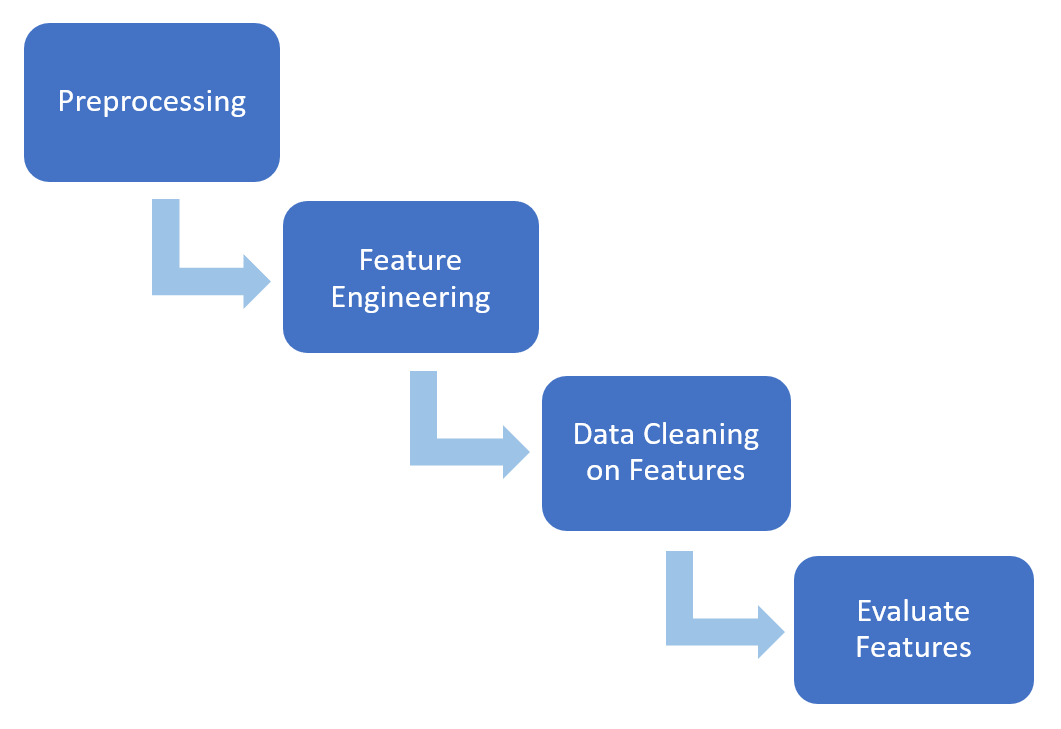

- Preprocessing

- Feature Engineering

- Data Cleaning on Features

- Evaluate Features

- All of the above

#### Question 2

Assume you're analyzing images like the one below and you want to engineer features that will determine if there is a stop sign in the image. You decide that identifying red objects in the image would be a useful feature. 

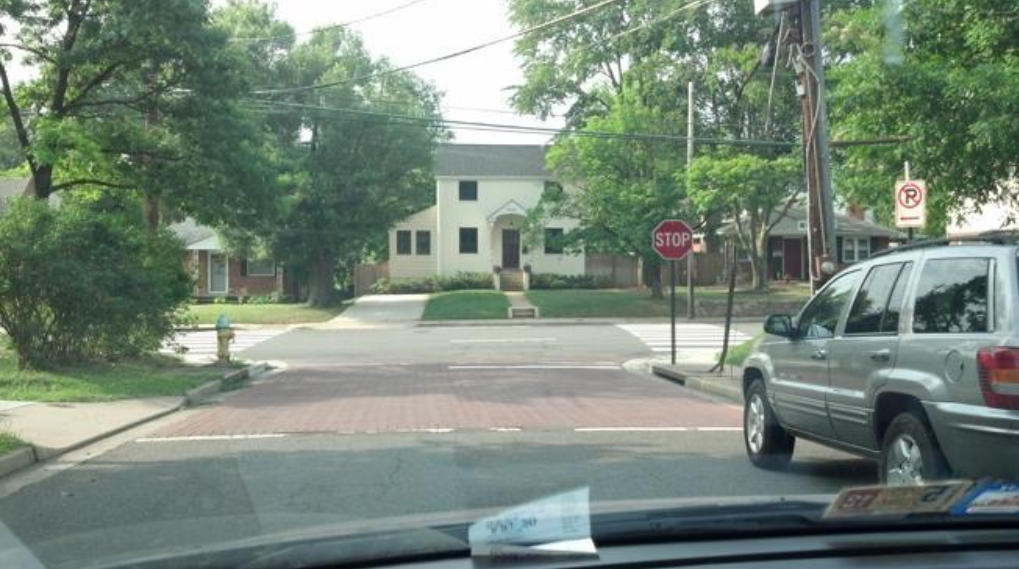

After some trial and error, you come up with a method that detects the red stop sign but also the red brake lights from the backs of cars. Before abandoning this method, you find that you can remove the detected brake lights from your feature set by removing objects of a particular size and shape.

Removing these objects is which step of the feature engineering workflow?

- Preprocessing

- Feature Engineering

- Data Cleaning on Features

- Evaluate Features

#### Question 3

For problems 3-5, you'll be using a timetable with accelerometer data recorded with a cell phone. The sensorlog_20190714.mat file is in the Module 5 folder. Load the data and preview the table with the following code.

`load sensorlog_20190714.mat ``Acceleration`

`Acceleration`

This data is not regularly sampled, meaning the time step between data points is not always consistent. 

Use the retime function to regularly resample the Acceleration timetable at 50 Hz. How many data points are there in each signal of the timetable after resampling? In other words, what is the height of the new timetable? 

For an example of how to use retime, refer back to Synchronizing Data with Timetables.

load sensorlog_20190714.mat Acceleration
Acceleration

Acceleration = 3659×3 timetable
           Timestamp               X         Y         Z   
    ________________________    _______    ______    ______

    14-Jul-2019 18:50:47.460    -2.3973    4.8675    8.5014
    14-Jul-2019 18:50:47.479    -2.4019    4.7424    9.3153
    14-Jul-2019 18:50:47.498    -1.8466    4.5503    8.7102
    14-Jul-2019 18:50:47.517    -1.6383    4.5592    8.2152
    14-Jul-2019 18:50:47.536    -1.6238    4.5992    8.3159
    14-Jul-2019 18:50:47.555    -1.9466    4.6871    8.0435
    14-Jul-2019 18:50:47.574    -1.9704    4.7821    7.9887
    14-Jul-2019 18:50:47.593    -1.5395     4.602    8.0393
    14-Jul-2019 18:50:47.612    -1.2953     4.453     8.511
    14-Jul

#### Question 4

Below is a stackedplot of Acceleration. 

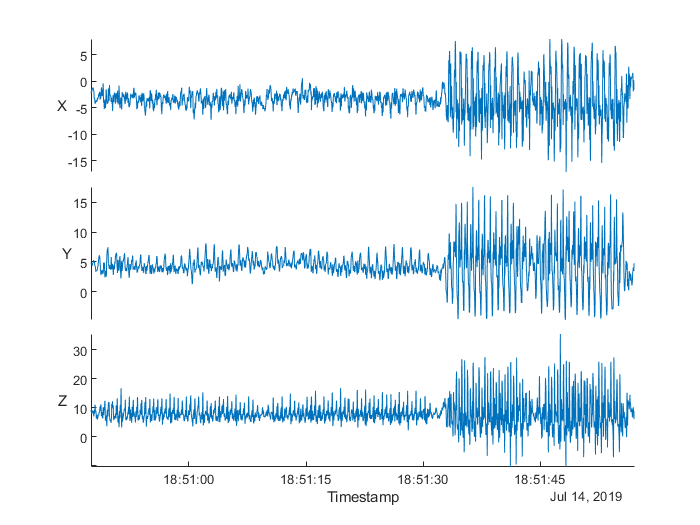

This accelerometer data was recorded with a person walking for approximately 45 seconds followed by jogging. The transition occurred around 18:51:32. 

Which summary statistic(s) would likely be useful as features to discriminate between the two activities?

- Mean

- Standard Deviation

- Median

- Spectral Centroid

- All of the above

#### Question 5

With your retimed Acceleration variable, use the following code to extract a portion of the Y-channel signal when the person was jogging. The detrend function is used to subtract off any linear trend in the data, including any offset (that is, it moves the mean near 0).

`jogSignal = detrend(Acceleration``.``Y``(``Acceleration``.``Timestamp`` > "``14``-``Jul``-``2019` `18``:``51``:``32``"))`

What is the rate of jogging of this signal in Hz? In other words, what is the *fundamental frequency *of this signal? 

To answer this question, you first need to calculate a frequency spectrum of this signal using the function periodogram (don't forget the sample rate was 50 Hz). 

Then, use the "Find Local Extrema" Live Editor Task to find the most prominent peak in the spectrum.  Refer back to [Finding Peaks] for a demonstration of the Live Editor Task. 

#### Question 6

For the rest of the quiz, you'll be working with data in the following image of printed text. This file is included in MATLAB so you won't find it in the Module 5 folder. Load the image with the following code. Notice the illumination is very uneven.

`textImage = imread("printedtext.png");`

`imshow(textImage)`

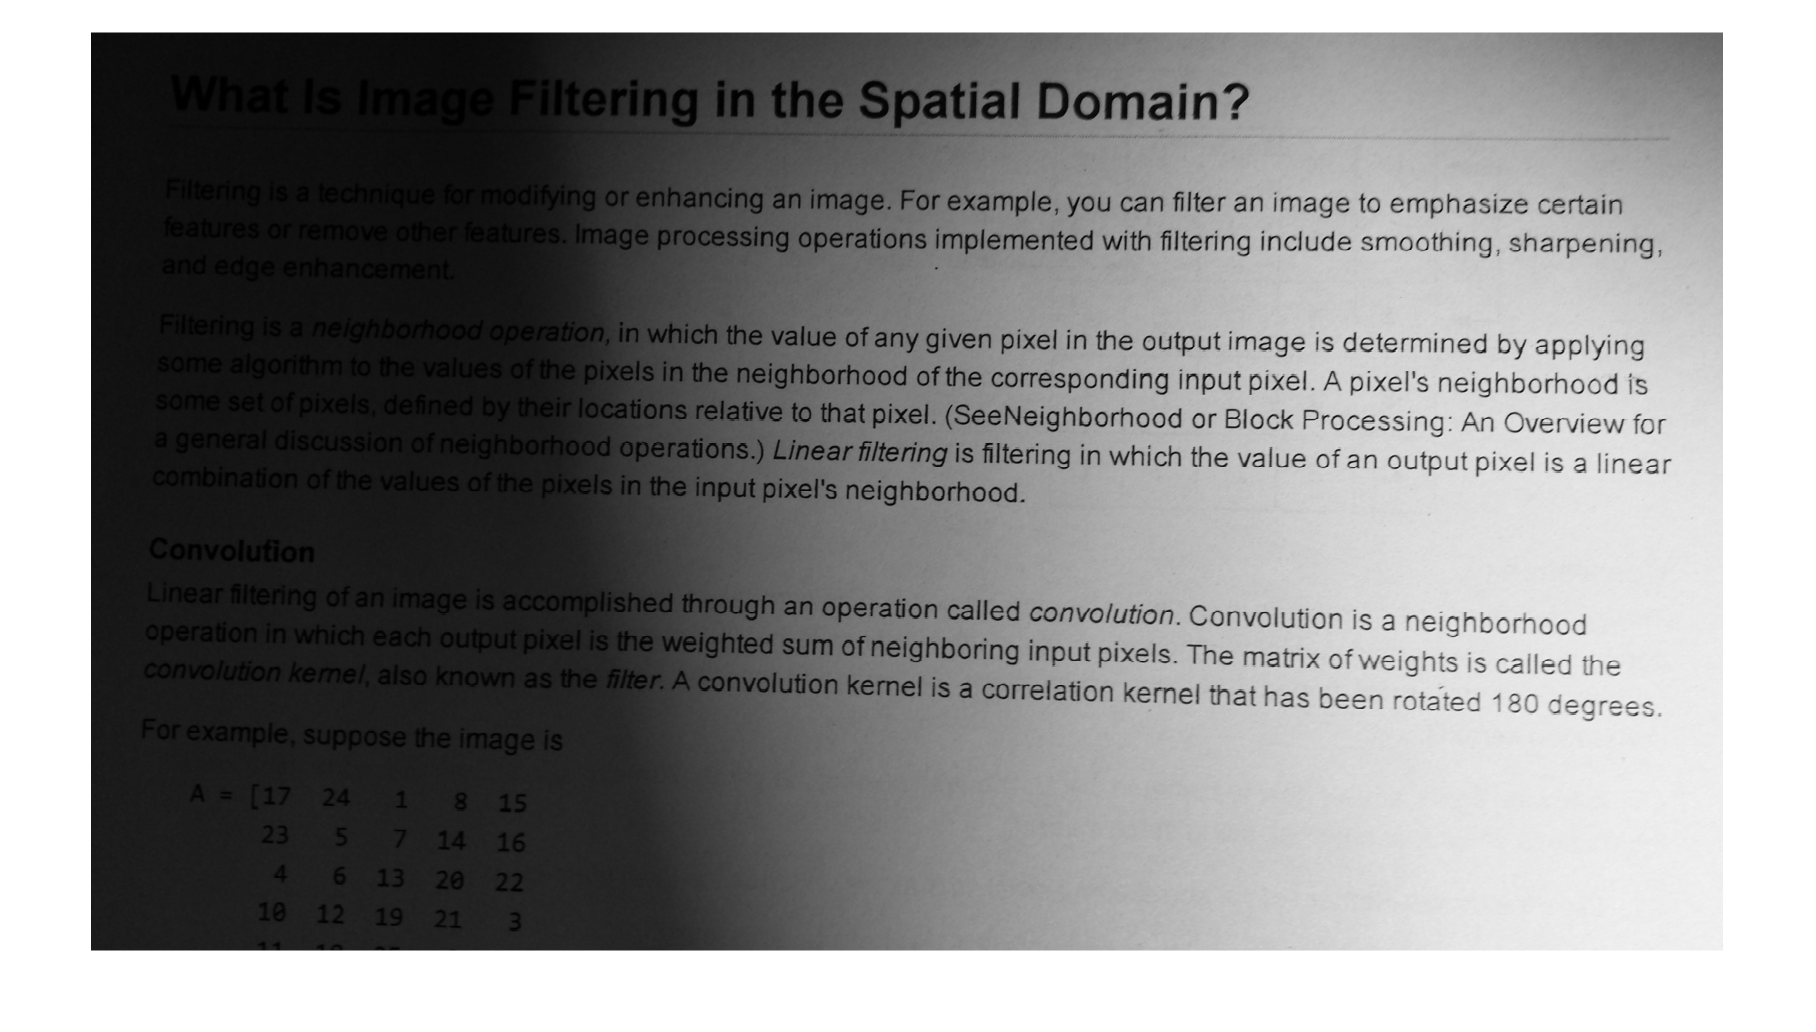

Load textimage in the Image Segmenter App by selecting "Load Image from Workspace" and try the different segmentations listed below. Which approach gives you this segmented image?

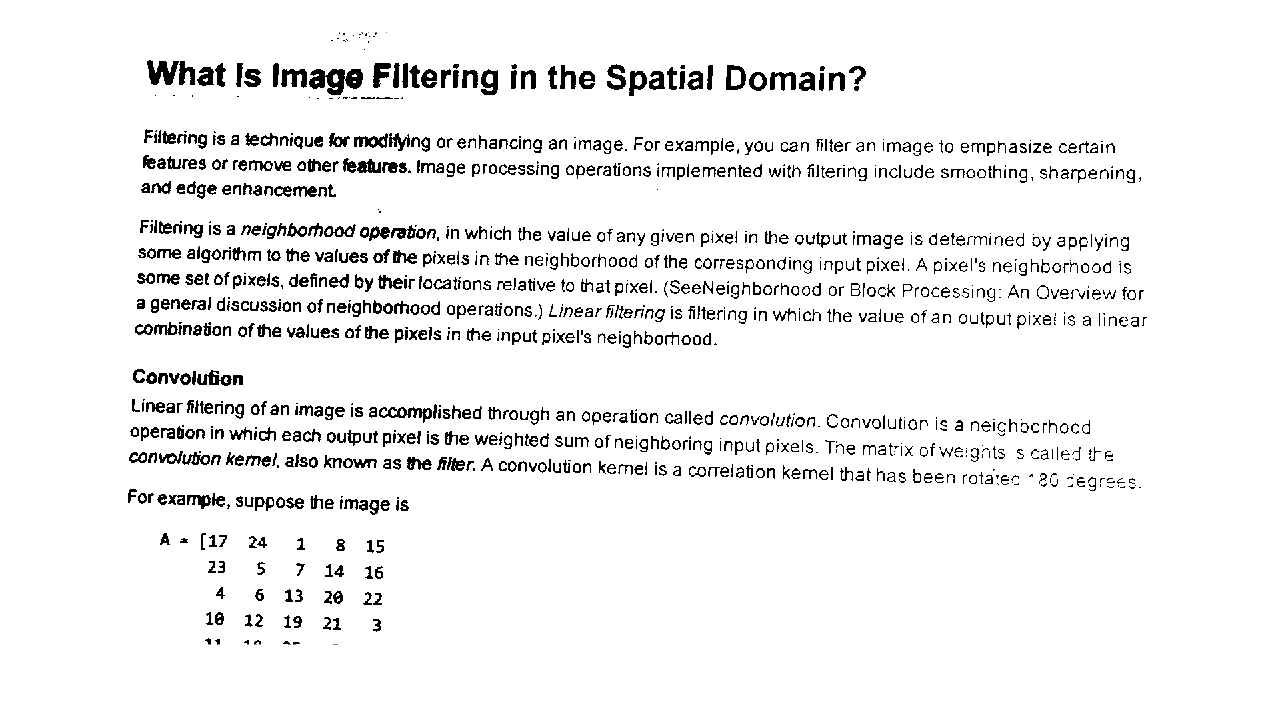

- Adaptive threshold with a "bright" foreground polarity and a "Sensitivity" value of 90

- Manual threshold with a "Threshold" value of of 200

- Global Threshold

- Adaptive threshold with a "bright" foreground polarity and a "Sensitivity" value of 50

- Manual threshold with a "Threshold" value of 60

#### Question 7

Generate a function of your segmentation from the previous question and save it as "segmentTextImage." Which app would you use to test the segmentation on more pages of text?

- Registration Estimator

- Image Batch Processer

- Color Thresholder

- Image Region Analyzer

- None of the above

#### Question 8

Use your segmentTextImage function with the code below to turn the image of text into a string variable in MATLAB for further text processing.

`BW`` = segmentTextImage(textImage);`

`ocrOutput = ocr(``BW``);`

`ocrText = string(ocrOutput.``Text``)`

`imshow(``BW``)`

The OCR function performs "Optical Character Recognition" on the image to extract the text from the image. Compare the text in the variable ocrText with the segmented image. You'll see that most characters were correctly identified with only a few mistakes.

Create a tokenized document using the string ocrText. Refer back to [Feature Engineering With Text] to see a demonstration.  What is the most common token in the raw text?

- "."

- ","

- "is"

- "image"

- "the"

- "pixel"

#### Question 9

Remove any punctuation and stop words from your set of tokens. Then, normalize the words with the "lemma" style to reduce the tokens with different parts of speech to their root form. After performing these cleaning steps, what is the most common token?